# Group Assignment 4

## Mark Belanger, Carter Harris, Meagan Lipsman

### **1. Frequency domain filtering.** 

Do the following for 2 images of your choice **(10 points each for all sub-parts = 30 points total)**

- Apply low pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Apply high pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Add noise to your images. Does spatial domain filtering (median filtering, spatial domain gauss filter, etc.) work better to remove this noise or frequency domain filtering? 

#### Part 1 - low pass filtering

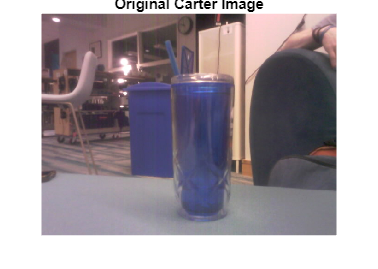

% Low Pass Filtering 
carter = imread("carter.jpg");
arcaid = imread("ARCAid.jpg");

imshow(carter)
title("Original Carter Image")

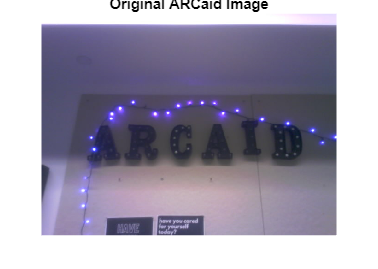

imshow(arcaid)
title("Original ARCaid Image")

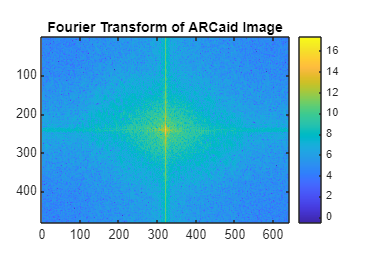

arc_gray = im2gray(arcaid);
arc_fft = fft2(arc_gray);

Y3 = fftshift(arc_fft);
imagesc(log(abs(Y3)));
axis("equal")
title("Fourier Transform of ARCaid Image")
colorbar

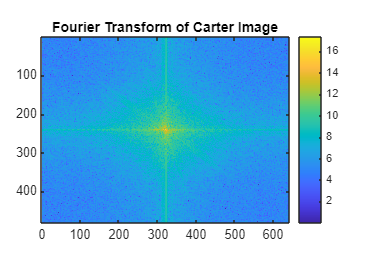

carter_gray = im2gray(carter);
carter_fft = fft2(carter_gray);

Y4 = fftshift(carter_fft);
imagesc(log(abs(Y4)));
axis("equal")
title("Fourier Transform of Carter Image")
colorbar

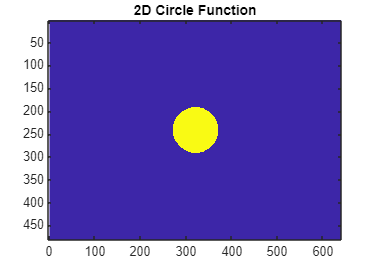

[xx, yy] = meshgrid(-320:319,-240:239);
Z_circ = zeros(size(xx));
Z_circ((xx.^2+yy.^2)<50^2) = 1;
imagesc(Z_circ)
axis equal
title("2D Circle Function")

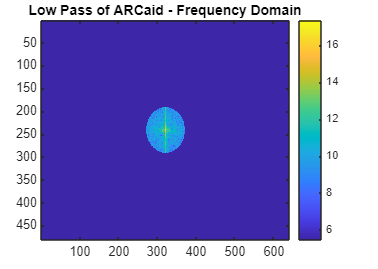



low_pass_arcaid = Y3 .* Z_circ;
imagesc(log(abs(low_pass_arcaid)))
title("Low Pass of ARCaid - Frequency Domain")
colorbar

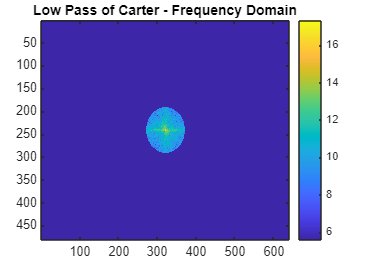


low_pass_carter = Y4 .* Z_circ;
imagesc(log(abs(low_pass_carter)))
title("Low Pass of Carter - Frequency Domain")
colorbar

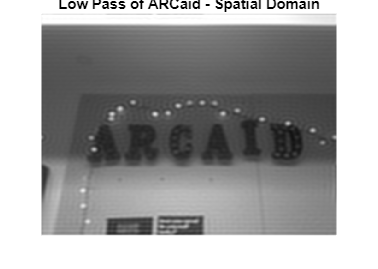


spacial_lp_arcaid = ifft2(ifftshift(low_pass_arcaid));
imshow(uint8(spacial_lp_arcaid))
title("Low Pass of ARCaid - Spatial Domain")

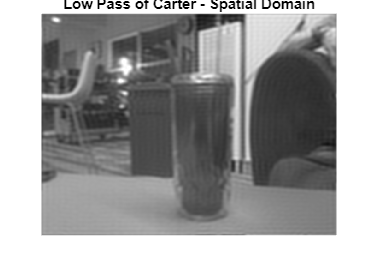


spacial_lp_carter = ifft2(ifftshift(low_pass_carter));
imshow(uint8(spacial_lp_carter))
title("Low Pass of Carter - Spatial Domain")

#### Part b - high pass filtering

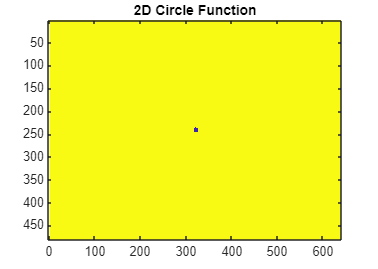

[xx, yy] = meshgrid(-320:319,-240:239);
high_pass = zeros(size(xx));
high_pass((xx.^2+yy.^2)>5^2) = 1;
imagesc(high_pass)
axis equal
title("2D Circle Function")

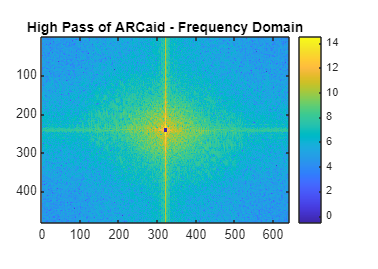



high_pass_arcaid = Y3 .* high_pass;
imagesc(log(abs(high_pass_arcaid)))
title("High Pass of ARCaid - Frequency Domain")
axis equal
colorbar

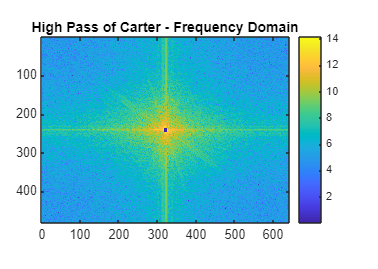


high_pass_carter = Y4 .* high_pass;
imagesc(log(abs(high_pass_carter)))
title("High Pass of Carter - Frequency Domain")
axis equal
colorbar

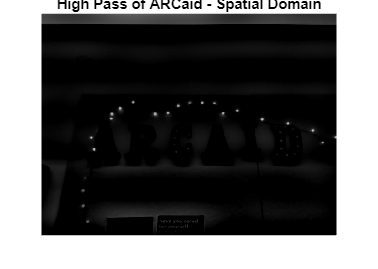


spacial_hp_arcaid = ifft2(ifftshift(high_pass_arcaid));
imshow(uint8(spacial_hp_arcaid))
title("High Pass of ARCaid - Spatial Domain")

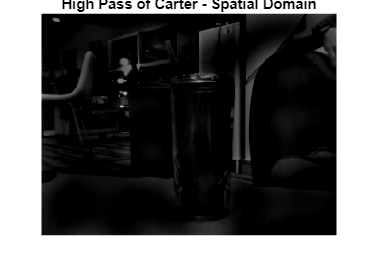


spacial_hp_carter = ifft2(ifftshift(high_pass_carter));
imshow(uint8(spacial_hp_carter))
title("High Pass of Carter - Spatial Domain")

The high-pass filtering has a much more drastic impact on the image compared to the low-pass filtering, considering that the image is highly concentrated at the lower frequencies.

#### Part c - adding and filtering noise

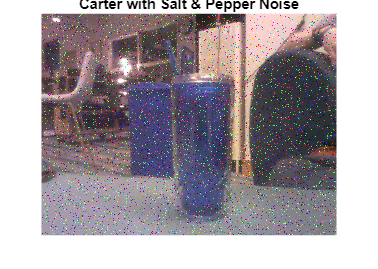

noise_carter = imnoise(carter, "salt & pepper");

imshow(noise_carter)
title("Carter with Salt & Pepper Noise")

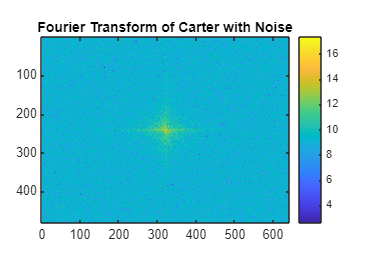


n_carter_gray = im2gray(noise_carter);
n_carter_fft = fft2(n_carter_gray);

noise_fft_carter = fftshift(n_carter_fft);
imagesc(log(abs(noise_fft_carter)));
axis("equal")
title("Fourier Transform of Carter with Noise")
colorbar

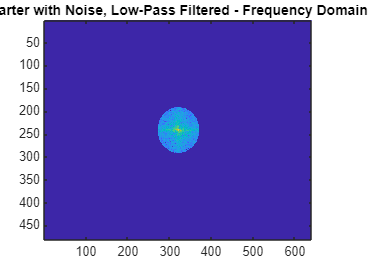


noise_lp_carter = noise_fft_carter.* Z_circ;
imagesc(log(abs(noise_lp_carter)))
title("Carter with Noise, Low-Pass Filtered - Frequency Domain")

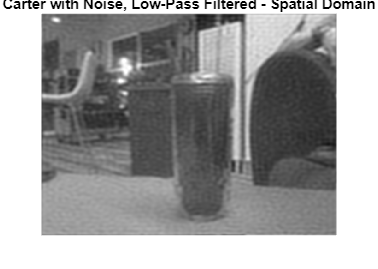


spacial_noise_carter = ifft2(ifftshift(noise_lp_carter));
imshow(uint8(spacial_noise_carter))
title("Carter with Noise, Low-Pass Filtered - Spatial Domain")

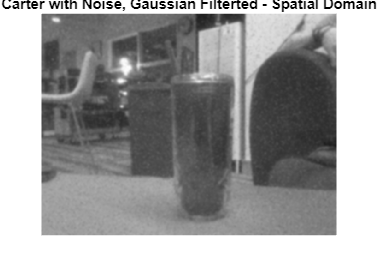


sigma = 2;
carter_filter = imgaussfilt(noise_carter,sigma);
carter_gray = im2gray(carter_filter);
imshow(carter_gray)
title("Carter with Noise, Gaussian Filterted - Spatial Domain")

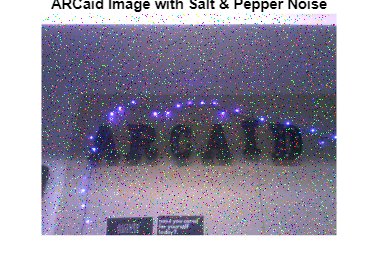

noise_arc = imnoise(arcaid, "salt & pepper");
imshow(noise_arc)
title("ARCaid Image with Salt & Pepper Noise")

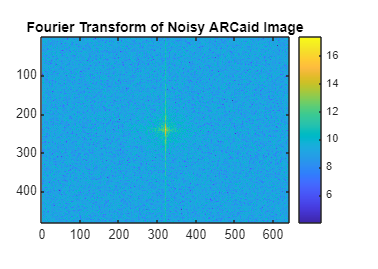


n_arc_gray = im2gray(noise_arc);
n_arc_fft = fft2(n_arc_gray);

noise_fft_arc = fftshift(n_arc_fft);
imagesc(log(abs(noise_fft_arc)));
axis("equal")
title("Fourier Transform of Noisy ARCaid Image")
colorbar

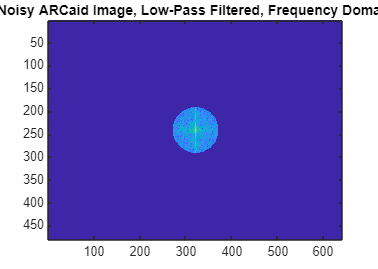


noise_lp_arc = noise_fft_arc.* Z_circ;
imagesc(log(abs(noise_lp_arc)))
title("Noisy ARCaid Image, Low-Pass Filtered, Frequency Domain")

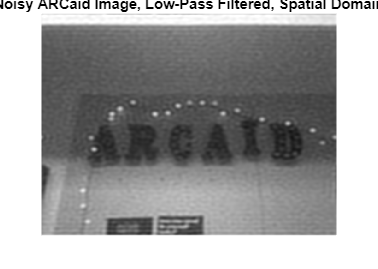


spacial_noise_arc = ifft2(ifftshift(noise_lp_arc));
imshow(uint8(spacial_noise_arc))
title("Noisy ARCaid Image, Low-Pass Filtered, Spatial Domain")

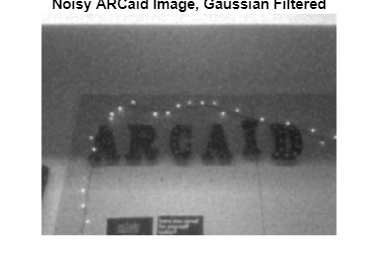


sigma = 2;
arc_filter = imgaussfilt(noise_arc,sigma);
arc_gray = im2gray(arc_filter);
imshow(arc_gray)
title("Noisy ARCaid Image, Gaussian Filtered")

Overall, for our images, the frequency domain (low-pass/high-pass) and spatial domain filters (Gaussian) worked fairly similarly with the added Salt & Pepper noise. Both generally removed the noise but introduced more blurring into the images. 

The frequency domain filters did tend to appear more noisy/deviated from the original image compared to the Gasussian spatial domain filters. That being said, the frequency domain filters preseverd a greater constrast between parts within the image and particularly between different parts of the image and the background. The light sources (string lights) were also much more pronounced in the ARCaid image in particular.

Given these findings, choosing which filter to use again becomes a decision best made based on the intended usecase of the filtering system. A system where sharper edges and contrast (ie edge detection or something similar) might benifit more from an implementation of the low pass frequency domain filter shown here. On the other hand, an image that relies more on fine details, perhaps for identification or classification, the spatial domain filters might be a better fit.

**2. Deconvolution and** **Deblurring.** MATLAB and other programming platforms allow you to do a blind deconvolution or use some pre-designed functions to achieve deblurring. Try out the given sample code [trydeconv.m](https://olin.instructure.com/courses/819/files/186973?wrap=1)[ ](https://olin.instructure.com/courses/819/files/186973/download?download_frd=1)on some of your images. What are the pros and cons of these pre-designed functions? Pre-designed functions estimate the blurring kernel for you. Research and explain any two methods of estimating a deblurring kernel without using pre-designed functions? You can use any material available to do your research – youtube videos, research papers, tutorials – whatever your group chooses. **(30 points).** (might be helpful to review [MATLAB summary of blind deconvolution](https://www.mathworks.com/help/images/ref/deconvblind.html)).

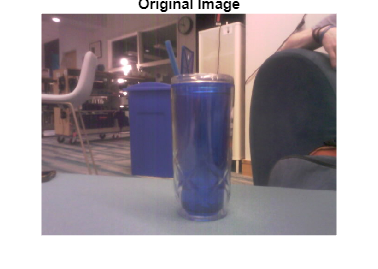

I = imread('carter.jpg');
figure; imshow(I); title('Original Image');

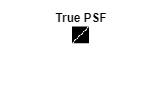


PSF = fspecial('motion',28,45);% Create the PSF
figure; imshow(PSF,[]); title('True PSF');

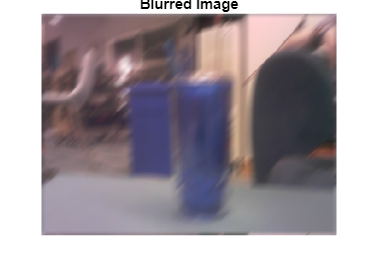


Blurred = imfilter(I,PSF,'circ','conv');% Simulate the blur
figure; imshow(Blurred); title('Blurred Image');

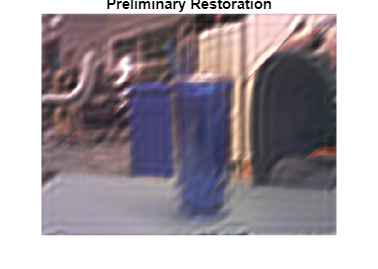


INITPSF = ones(size(PSF));
[J P]= deconvblind(Blurred,INITPSF,10);
figure; imshow(J); title('Preliminary Restoration');

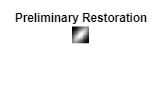

figure; imshow(P,[]);
title('Preliminary Restoration');

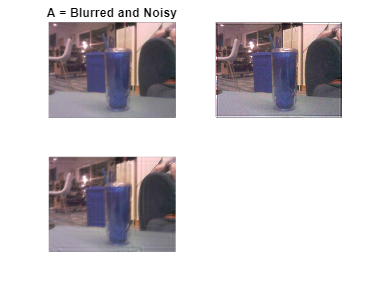


PSF2 = fspecial('gaussian',7,10);
V = .0001;
BlurredNoisy = imnoise(imfilter(I,PSF2),'gaussian',0,V);

J1= deconvlucy(BlurredNoisy,PSF2);
J2= deconvlucy(Blurred,PSF);


% Display the results.
figure;
subplot(221);imshow(BlurredNoisy);
title('A = Blurred and Noisy');
subplot(222);imshow(J1);
subplot(223);imshow(J2);

Pros of predesigned functions:

- Simple/quick to use

- Accessible to the wider population (people with little image processing knowledge) 

- Often easy to find example code

- Reduces sources of error because complex math is already done

Cons of predesigned functions:

- Black box of code 

- Limited options for customization and optimization

- Encourages copy and pasting without fully understand 

- Frequently produces unexpected *and unexplainable* results 

Overall, the predesigned MATLAB functions for deblurring are a great first step to take, whether you're just starting out in image processing or want to figure out a more detail direction to take processing a particular set of images. Built-in functions are great in this regard as they allow you to try a number of different functions without having to implement code for each. However, beyond this exploration, there is quite limited customization that can be done to make a particular function more applicable for a given set of images. If the deblurring is not achieved adequetly using these first tests, a custom function for deblurring the images will likley be nessesary.

There are many ways to find and optimize this kenel, may of which use a number of concepts in machine learning and optimization. A few ways to find a better kenel researched by our team are detailed below:

**Method 1: Use edge detection to identify & reconstruct edges, therefore reconstructing the rest of the image (hopefully).** Use the image gradiant to identify patterns in the image that likely represent edges. The paper by Wang and Yang, cited below, proposes several patterns in the image gradient to achieve this. Base your kernel off of this gradient and apply it to the whole image.

    The gradiant of an image is the "directional change in the intensity or color in an image" (Wikipedia). Edge are going to be the easiest to identify since the gradient will be more apparent. For example, the graident of a black line on a white background should be easier to determine than a image of all the same color. Since the blur is uniform across the whole image we can assume that the gradient (blur) alone the edges will be the same for every point on the image. A kenel that would restore this edge would therefore likely restore most of the image.

Citation: Yang, Chunyu, and Weiwei Wang. “Edge Enhancing Based Blind Kernel Estimation for Deep Image Deblurring.” Circuits, Systems, and Signal Processing, 21 Sept. 2024, [https://doi.org/10.1007/s00034-024-02865-1](https://doi.org/10.1007/s00034-024-02865-1). Accessed 11 Oct. 2024.

**Method 2: Minimum mean square error (Wiener) filtering**

Another method that can be used to deblur images, and particularly those with added noise in addditon to the blur, is minmum mean square error filtering. This is also sometimes known as Wiener filtering. This method of filtering works by minimzing the error between blurred image and the estimated original image, a process which works particularly well to remove statistical anomlies in the image related to the deblurring.

Citation: Gonzalez, Rafael C, and Richard E Woods. *Digital Image Processing*. 4th ed., New York, NY, Pearson, 2018.

**3. Histogram equalization.** Use histogram equalization as an image enhancement technique on two images of your choice. If you used inbuilt functions (e.g. histeq in MATLAB, or cv2.equalizeHist() in OpenCV), did you see any limitations of these inbuilt functions? If yes, what are they? **(10 points).**

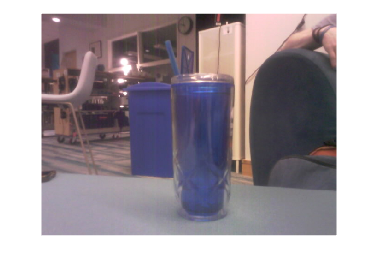

figure()
imshow(carter)

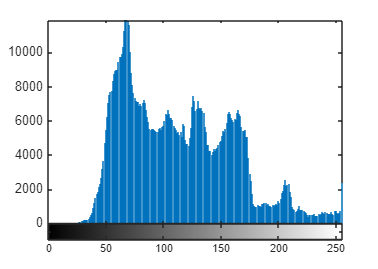

imhist(carter);

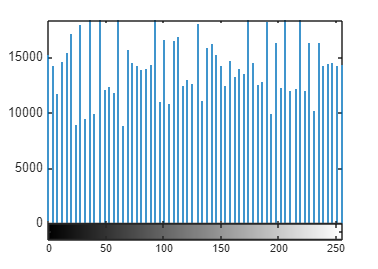

normal_carter = histeq(carter);
imhist(normal_carter);

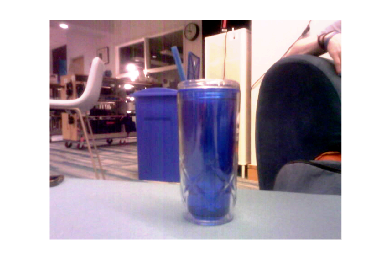

imshow(normal_carter)

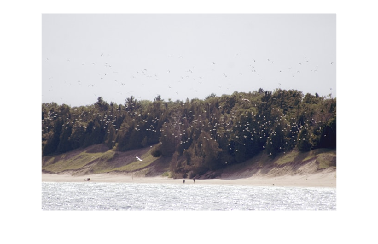

beach = imread("beach.jpg");
figure()
imshow(beach)

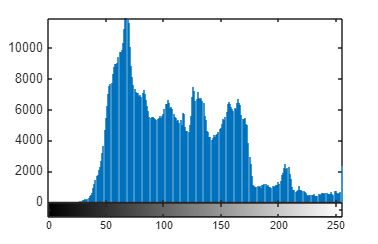

imhist(carter);

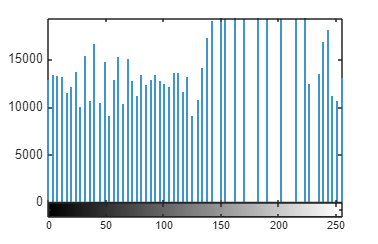

normal_carter = histeq(beach);
imhist(normal_carter);

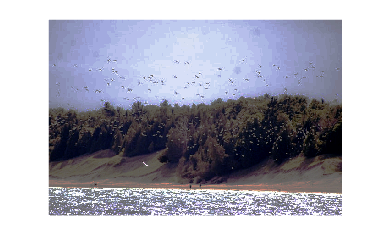

imshow(normal_carter)

Image citation: Meinert, Gabriel.* A Flock of Birds Flying over a Beach*, 22 Mar. 2023, unsplash.com/photos/a-flock-of-birds-flying-over-a-beach-N1SRehzlgnI.

We tried histogram equlization on two seperate images. First, we used the image of Carter, as it has become our standard test image for scenarios where we wish to see the impacts on color, as happens with histogram equalization. Upon using MATLAB's built-in histeq() function, it was immedietly apparent the equalization because of the increased saturation and overall brightness of the image, in which the colors appeared much more vivid that the original image. This was especially apprent for Carter, while the background was only impacted mildly.

For our second image, we wanted to explore this color and saturation impact further, so we chose an image of a beach that had fairly muted colors to begin with. Upon running MATLAB's histeq on this image, it also greatly changed the colors in the image, but in a way much different compared to the image of Carter. This image came out much darker than the input image, which although muted, was fairly bright all around. The realated saturation-like effect seen in the Carter image didn't fully manifest for the beach.

Overall, this highlights the challenge of using MATLAB's built-in functions for histogram equalization. As with any pre-made function, the biggest challenge is that they're a black box. We're not entirley sure what the code used to implmenet them looks like, so it is impossible to predict how the function will behave in all situations. This can produce different and unexpected results between different images, and the functions really don't have any additional ways to limit/control/standardize the output as you would have implementing the function manually.

**4. Some more filtering.** You are provided with a code ‘[Frequency_LPF.m](https://olin.instructure.com/courses/819/files/186868?wrap=1)[ Download Frequency_LPF.m](https://olin.instructure.com/courses/819/files/186868/download?download_frd=1)’). It implements 3 types of low pass filters in frequency domain – ideal, butterworth and gaussian. Run this code for an image of your choice. Comment on the effects of these filters in your image. Feel free to play around with parameters and those changes to your comments. **(10 points).**

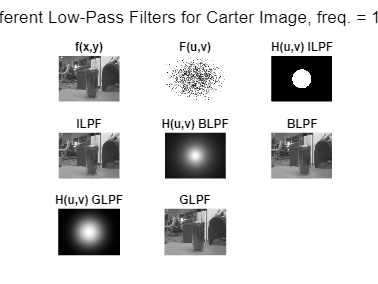

frequencylpf('carter.jpg', "Carter", 100)

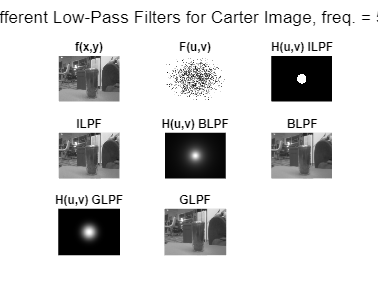

frequencylpf('carter.jpg', "Carter", 50)

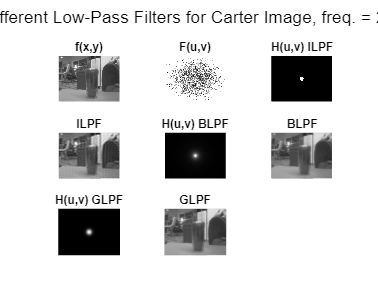

frequencylpf('carter.jpg', "Carter", 20)

**brief points**

- **at 100 they just blurred a little - looked very similar**

- **at 50 we started to see some differences in the ideal low pass filter where you were getting the weird lines - looked like you tried to blur and thne unblur**

- **at 20 the above mentioned difference was more apparant and there were slight differences in the gaus and butterworth filters where the gause had some more contrast in carters facial features **

We ran the provided filters for three different descending cutoff frequencies: 100, 50, and 20.

At the highest frequency, the filters all looked more or less the same, as there was very little higher frequency signals in the image to be filtered out.

Once we reached our "medium" frequency, 50, the effects between the ideal low-pass filter and the Gaussian and Butterworth filters started to become more apparent. The ideal low pass filter began to have a fairly signifcant amount of artificating around the image. This artificating resembled the images earlier in this assignment that had been blurred and unblurred using blind deconvolution. At this higher frequence, there was not a major discernable difference between the Gaussian and Butterworth filters.

Once we reached the lowest frequency we tested, 20, the previously described effects of the ideal low-pass filter became more intense, and lots of detail in the image was lost. Both the Gaussian and Butterworth images reamined looking generally blurred, but at this low of a frequency, small differences were noticeable. The Gaussian filter retained slightly more constrast in some of the smaller details of the image, such as around Carter's facial features, compared to that of the Butterworth filter. The Butterworth filter, on the other hand, had slightly more defined lines around Carter in the image. Given this information, depending on what features we're attempting to be pulled out of the image, both the Gaussian and Butterworth low-pass filters could be potentially useful for different situations.

Provided FrequencyLPF function

function frequencylpf(imagepath, titlevar, freq)
    figure
    img = imread(imagepath);
    gimg=rgb2gray(img);
    subplot(331)
    imshow(gimg)
    title('f(x,y)')
    %% Ideal low pass
    P=size(gimg);
    M=P(1);N=P(2);
    F=fft2(gimg,M,N);
    subplot(332)
    %imshow(uint8(abs(fftshift(F))));
    imshow(uint8(abs((F))));
    title('F(u,v)')
    u0=freq; %remove freq greater than u0
    u=0:(M-1);
    v=0:(N-1);
    idx=find(u>M/2);
    u(idx)=u(idx)-M;
    idy=find(v>N/2);
    v(idy)=v(idy)-N;
    [V,U]=meshgrid(v,u);
    D=sqrt(U.^2+V.^2);
    H=double(D<=u0);
    % display
    subplot(333)
    imshow(abs(fftshift(H)),[]);
    title('H(u,v) ILPF')
    subplot(334)
    G=H.*F;
    gideal=(ifft2(G));
    imshow(uint8(gideal))
    title('ILPF')
    %% Butterworth low pass
    n=1; %Butterworth filter of order n
    H= 1./(1 + (D./u0).^(2*n));
    subplot(335)
    imshow(abs(fftshift(H)));
    title('H(u,v) BLPF')
    subplot(336)
    G=H.*F;
    gbutter=(ifft2(G));
    imshow(uint8(gbutter))
    title('BLPF')
    %% Gaussian low pass filter
    H = exp(-(D.^2)./(2*(u0^2)));
    subplot(337)
    imshow(abs(fftshift(H)));
    title('H(u,v) GLPF')
    subplot(338)
    G=H.*F;
    ggauss=(ifft2(G));
    imshow(uint8(ggauss))
    title('GLPF')
    sgtitle("Different Low-Pass Filters for " + titlevar + " Image, freq. = " + u0)
end